Przykład 1

clear

fun = @(x)(1-x(1)).^2+(5*x(2)-x(1).^2).^2 % funkcja celu

fun = function_handle with value:
    @(x)(1-x(1)).^2+(5*x(2)-x(1).^2).^2



x0 = [-3,4]; %Warunki początkowe
% przy ograniczeniach liniowych:  x1-x2+4<=0  i  2x1+x2=-4
A = [1,-1];
b = -4;
Aeq = [2,1];
beq = -4;
ub=[10, 1.4];

% przy ograniczeniach nieliniowych "ellipseparabola(x)"
%  (x(1)^2)/9 + (x(2)^2)/4 <= 1
%   x(2) >= x(1)^2 - 1

options = optimset('Display','iter','PlotFcns',@optimplotfval)

options = struct with fields:
                   Display: 'iter'
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: []
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: @optimplotfval
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeSca

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    6.430250e+01    1.590e+00    1.581e+01
    1       6    2.377205e+01    8.059e-01    6.618e+01    9.902e-01
    2       9    1.693697e+01    3.161e-01    5.899e+00    4.521e-01
    3      12    1.517163e+01    2.031e-01    3.713e+00    2.695e-01
    4      15    1.398215e+01    5.652e-02    6.386e-01    1.583e-01
    5      18    1.373223e+01    0.000e+00    2.327e-01    8.338e-02
    6      21    1.365309e+01    0.000e+00    3.775e-02    4.621e-02
    7      24    1.364554e+01    0.000e+00    9.102e-03    5.127e-03
    8      27    1.364223e+01    0.000e+00    2.424e-04    2.302e-03
    9      30    1.364198e+01    8.882e-16    2.623e-06    1.787e-04


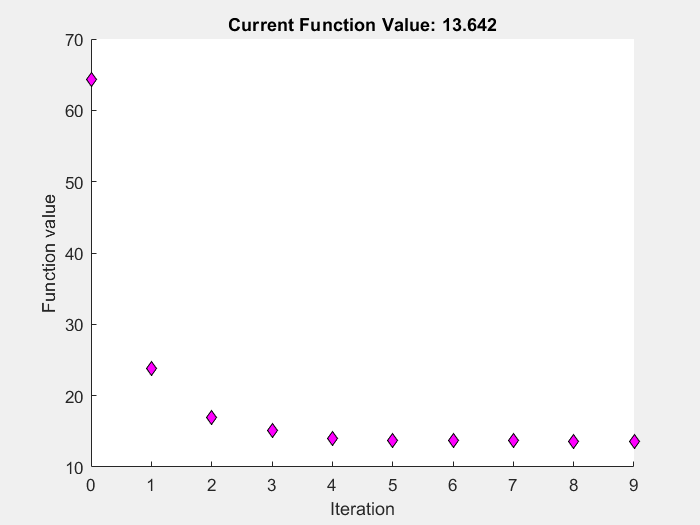


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =    -2.6667    1.3333



% Rozwiązanie:
nonlcon = @ellipseparabola; % ograniczenia nieliniowe
x = fmincon(fun,x0,A,b,Aeq,beq,[],ub,[],options) % bez ograniczeń nieliniowych

f=fun(x)

f = 13.6420

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    6.430250e+01    7.590e+00    7.253e+00
    1       6    6.296891e+01    7.374e+00    7.756e+00    5.561e-02
    2       9    6.238724e+01    7.356e+00    8.350e+00    6.184e-03
    3      12    6.138964e+01    7.327e+00    9.360e+00    1.100e-02
    4      15    6.138467e+01    7.326e+00    9.365e+00    5.464e-05
    5      18    8.471206e+00    1.904e+00    4.149e-02    1.100e+00
    6      21    7.985012e+00    1.580e+00    1.580e+00    2.375e-01
    7      24    1.139788e+01    1.441e+00    1.076e+00    3.663e-01
    8      27    1.339286e+01    1.549e+00    1.110e+00    1.050e-01
    9      30    1.511062e+01    1.506e+00    1.225e+00    1.298e-01
   10      33    1.637840e+01    1.608e+00    9.423e-01    4.610e-02
   11    

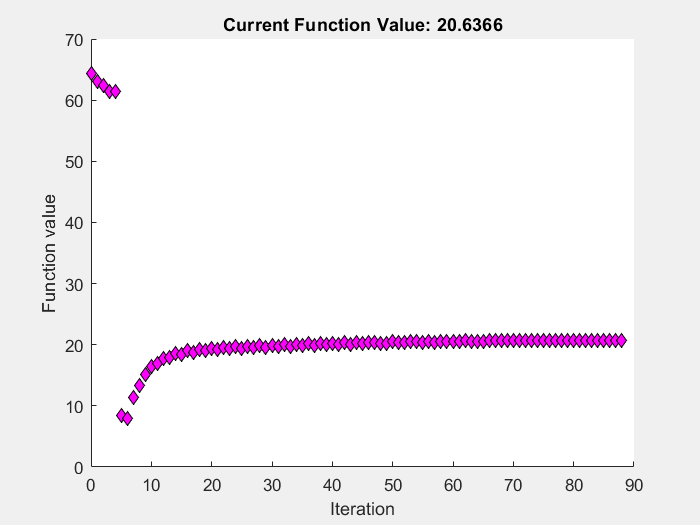


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



x =    -1.8638    1.4000


x = fmincon(fun,x0,A,b,Aeq,beq,[],ub,nonlcon,options) % z ograniczeniami nieliniowymi

f=fun(x)

f = 20.6366

Przykład 2

% x = fmincon(fun,x0,A,b,Aeq,beq)
% Przykłady ograniczeń liniowych równościowych i nierównościowych.
fun = @(x)100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
x0 = [0.5,0];
A = [1,2];
b = 1;
Aeq = [-2/abs(-2),1]

Aeq =     -1     1


beq = 1;
x = fmincon(fun,x0,A,b,Aeq,beq)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =    -0.6148    0.3852


%abs
%{
function [c,ceq] = mycon(x)
c = ... % Compute nonlinear inequalities at x.
ceq = ... % Compute nonlinear equalities at x.
%}
% Przykłady ograniczeń nieliniowych równościowych i nierównościowych.
% https://www.mathworks.com/help/optim/ug/nonlinear-constraints.html?searchHighlight=fmincon&s_tid=srchtitle_fmincon_8
% Anonymous Nonlinear Constraint Functions
% https://www.mathworks.com/help/optim/ug/nonlinear-constraints.html?searchHighlight=fmincon&s_tid=srchtitle_fmincon_8
c = @(x)[x(1)^2/9 + x(2)^2/4 - 1;
x(1)^2 - x(2) - 1];
ceq = @(x)tanh(x(1)) - x(2);
nonlinfcn = @(x)deal(c(x),ceq(x));
obj = @(x)cosh(x(1))+sinh(x(2));
opts = optimoptions(@fmincon,'Algorithm','sqp');
z = fmincon(obj,[0;0],[],[],[],[],[],[],nonlinfcn,opts)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =    -0.6530
   -0.5737


[cout,ceqout] = nonlinfcn(z)

cout =    -0.8704
         0


ceqout = 0

Zad 1.

clear;

Gs_Licz=[0 1];
Gs_Mian=poly([-0.5+1i, -0.5-1i, -1]);
Gs=tf(Gs_Licz,Gs_Mian);
step(Gs);
[Gs2_Licz,Gs2_Mian]=pade(0.5,3);
Gs2=tf(Gs2_Licz,Gs2_Mian);
Gs2=Gs*Gs2

Gs2 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



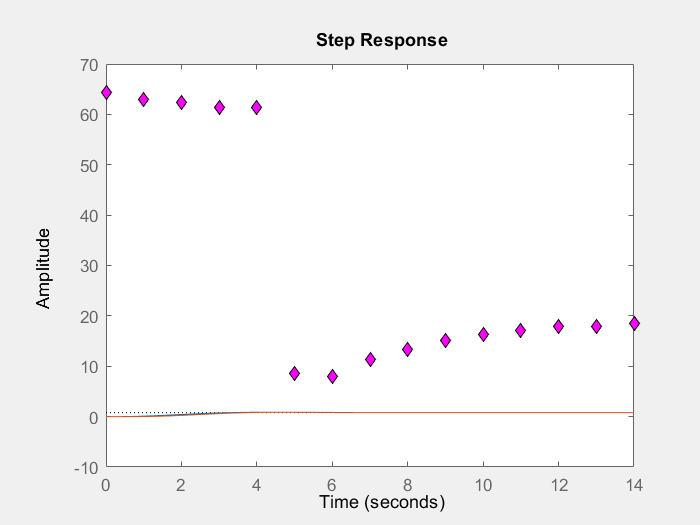

step(Gs2);

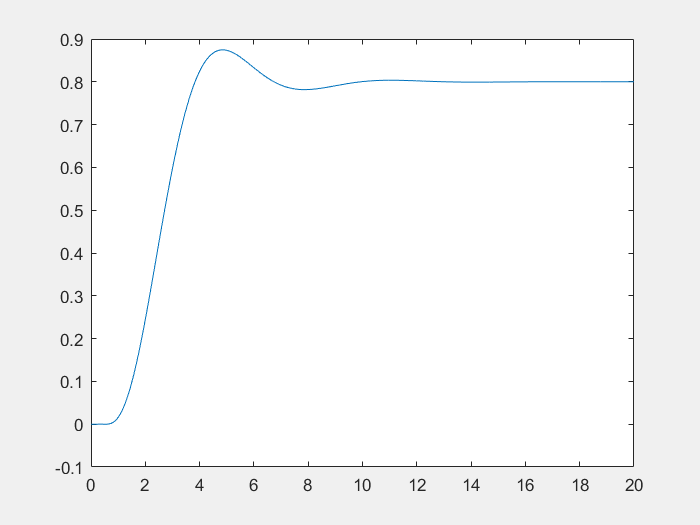


% Obiekt rzeczywisty - estymowany
global t; global y1;
Go = Gs2;
t=0:0.01:20;
y1 = step(t, Go);
plot(t, y1);


% x0 = [0,0,1,0]; % [[~~]/[~~]]
x0 = [1,0,0,0]; %

% options = optimset('Display','iter','PlotFcns',@optimplotfval);
[x,blad,exitflag] = fminsearch(@ident,x0)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 189.938018 



x =     0.0103   43.1371   -4.0209    2.2668


blad = 189.9380

exitflag = 0


% Obiekt estymujący G1
G2=tf([0 1],[x(1) x(2) x(3) x(4)])

G2 =
 
                     1
  ----------------------------------------
  0.0103 s^3 + 43.14 s^2 - 4.021 s + 2.267
 
Continuous-time transfer function.




%b=G2.Numerator{1, 1}
%a=G2.Denominator{1,1}
%[z,p,k] =tf2zp(b,a)

x0 = [1,0]; %, gdzie x0 = [x(1), x(2)], współczynniki estymowanej transmitancji G2=1/(x(1)s + x(2))
% Skrypt
G1=tf([0 1],[1 2 2.25 1.25])

G1 =
 
               1
  ---------------------------
  s^3 + 2 s^2 + 2.25 s + 1.25
 
Continuous-time transfer function.



[G1p_Licz,G1p_Mian]=pade(0.5,3)

G1p_Licz =     -1    24  -240   960


G1p_Mian =      1    24   240   960


G1p=tf(G1p_Licz,G1p_Mian)

G1p =
 
  -s^3 + 24 s^2 - 240 s + 960
  ---------------------------
  s^3 + 24 s^2 + 240 s + 960
 
Continuous-time transfer function.



G1=G1*G1p

G1 =
 
                   -s^3 + 24 s^2 - 240 s + 960
  --------------------------------------------------------------
  s^6 + 26 s^5 + 290.2 s^4 + 1495 s^3 + 2490 s^2 + 2460 s + 1200
 
Continuous-time transfer function.



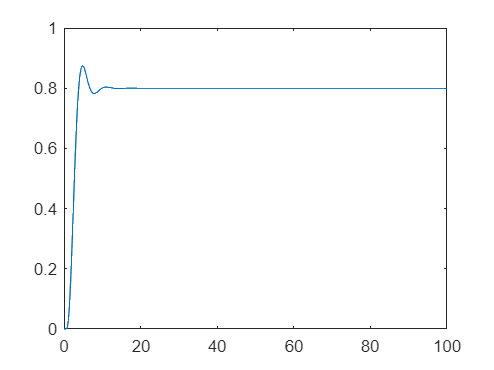

% Założyć przedział pomiarowy z krokiem t:
t=0:0.1:100;
[y1] = step(G1,t); % obiekt

plot(t, y1);


% options = optimset('Display','iter','PlotFcns',@optimplotfval);
[x, blad] = fminsearch(@ident2, x0)

x =     3.0444    1.2448


blad = 1.8069


% Obiekt estymujący G1
G2=tf([0 1],[x(1) x(2)])

G2 =
 
         1
  ---------------
  3.044 s + 1.245
 
Continuous-time transfer function.



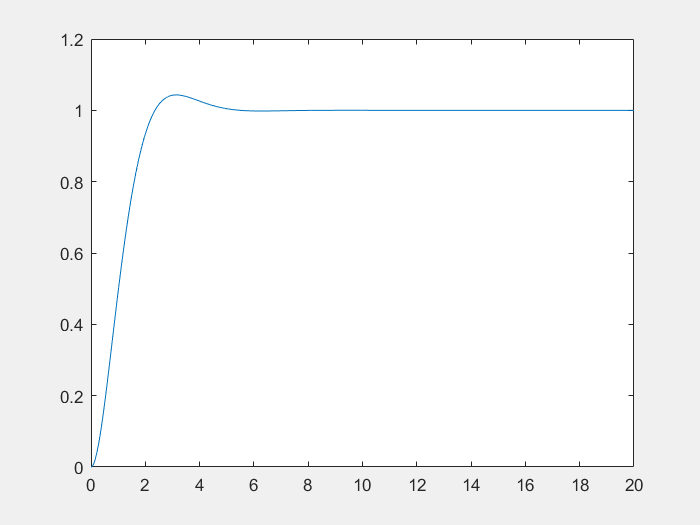

clear;
global Go; global t; global y1;
% Definicja obiektu sterowania
Gk_model = tf([0 2], [1 2 2]);
Go = tf([0 1], [1 2 2.25 1.25]);
t = 0:0.01:20;
y1 = step(t, Gk_model);
plot(t, y1);


% Ograniczenia na nastawy regulatora
lb = [0.2, 0.2, 0.2];
ub = [5, 10, 10];

% Ograniczenia równościowe
a = [];
b = [];
Aeq = [];
beq = [];

% Warunek początkowy
x0 = [0, 0, 0];

Bez ograniczeń

% Optymalizacja bez ograniczeń za pomocą fminsearch
[optimal_params, fval] = fminsearch(@identPID, x0);

% Wyświetlenie wyników optymalizacji
disp('Optymalne wartości Kp, Ki, Kd:')

Optymalne wartości Kp, Ki, Kd:


disp(optimal_params);

    1.3118    1.3115    1.4697




% Wyświetlenie wartości funkcji celu dla optymalnych parametrów
disp('Wartość funkcji celu dla optymalnych parametrów:')

Wartość funkcji celu dla optymalnych parametrów:


disp(fval);

    0.4501



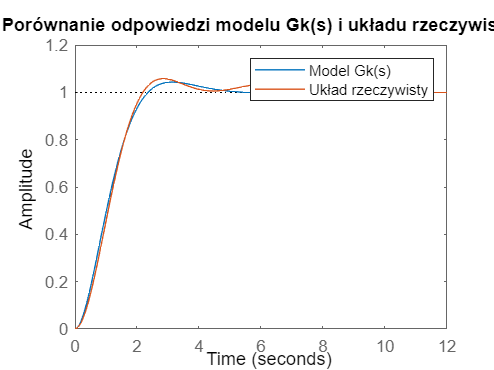


% Wyświetlenie porównania odpowiedzi układu rzeczywistego i modelu
figure;
step(Gk_model, feedback(Go*pid(optimal_params(1), optimal_params(2), optimal_params(3)), 1));
legend('Model Gk(s)', 'Układ rzeczywisty');
title('Porównanie odpowiedzi modelu Gk(s) i układu rzeczywistego');

Z ograniczeniami

% Wywołanie funkcji optymalizacyjnej fmincon
% options = optimset('Display', 'iter');
[optimal_params, fval] =  fmincon(@identPID, x0, a, b, Aeq, beq, lb, ub, @Hurwitz);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Wyświetlenie wyników
disp('Optymalne nastawy regulatora PID:');

Optymalne nastawy regulatora PID:


disp(optimal_params);

    1.3117    1.3115    1.4697




% Wyświetlenie wartości funkcji celu
disp('Wartość funkcji celu:');

Wartość funkcji celu:


disp(fval);

    0.4501



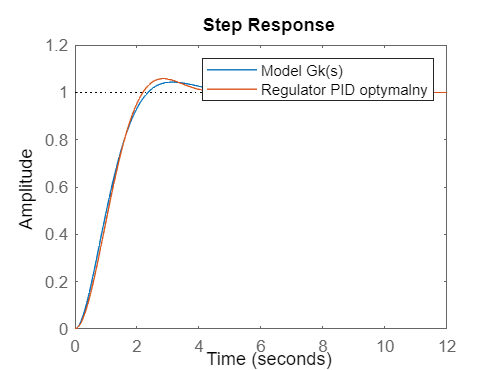


% Symulacja układu z optymalnymi parametrami
step(Gk_model, feedback(Go*pid(optimal_params(1), optimal_params(2), optimal_params(3)), 1));
legend('Model Gk(s)', 'Regulator PID optymalny');


% fynkcja gm zwraca zapas modułu

function blad = identPID(x)
    global Go; global t; global y1;
    
    G2 = feedback(Go*pid(x(1), x(2), x(3)), 1);
    y2 = step(G2, t); % dopasowanie

    e = y1-y2;
    blad= sum(e.^2);
    %blad= sum(e.^2) / length(e);
end

function [c,ceq] = Hurwitz(x)
    global Go;

    G2 = feedback(Go*pid(x(1), x(2), x(3)), 1);
    x = G2.Denominator{1};

    H=[x(2) x(4)  0 0 ; x(1) x(3) x(5) 0 ; 0 x(2) x(4) 0 ; 0 x(1) x(3) x(5)];
    H1=H(1,1);
    H2=H(1:2,1:2);
    H3=H(1:3, 1:3);

    Det_H1=det(H1);
    Det_H2=det(H2);
    Det_H3 = det(H3);
    Det_H=det(H);
    

    c(1) = -Det_H1;
    c(2) = -Det_H2;
    c(3) = -Det_H3;
    c(4) = -Det_H;
    ceq = [];

end

function blad = ident(x)
    global t; global y1;

    k = 0.8; % Odczytane z odpowiedzi skokowej G1
    T1 = x(1); T2 = x(2); T3 = x(3); c = x(4);

    G2 = tf([0 k], [T1 T2 T3 c]);
    y2 = step(G2,t); % dopasowanie

    e = y1-y2;
    blad= sum(e.^2);
    %blad= sum(e.^2) / length(e);
end

function blad = ident2(x)
    global t; global y1;

    k = 1;

    G2 = tf([0 k], [x(1) x(2)]);
    y2 = step(G2,t); % dopasowanie

    e = y1-y2;
    blad= sum(e.^2);
    %blad= sum(e.^2) / length(e);
end

function [c,ceq] = ellipseparabola(x)  % funkcja ograniczeń nieliniowych
    c(1) = (x(1)^2)/9 + (x(2)^2)/4 - 1;
    c(2) = x(1)^2 - x(2) - 1;
    ceq = [];
end